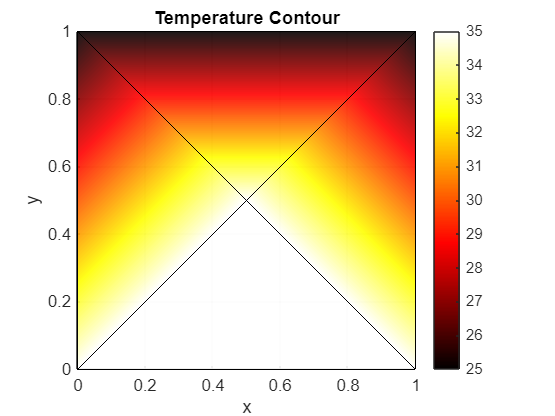

clc; clear;

% Parameters
k = 50;                      % Thermal conductivity (W/m-K)
T0 = 25;                     % Dirichlet BC on right side
q_mag = 1000;                % Heat source magnitude (W/m²)
center_node_id = 5;          % Index of center node

% Node coordinates (4 corners + center)
nodes = [0 0;    % Node 1
         1 0;    % Node 2
         1 1;    % Node 3
         0 1;    % Node 4
         0.5 0.5]; % Node 5 (center)

% Mesh: 4 triangles intersecting at center
elements = [1 2 5;
            2 3 5;
            3 4 5;
            4 1 5];

% Initialize global stiffness matrix and force vector
K = zeros(5);
F = zeros(5,1);

% Q matrix for linear triangular element
Q = [1 0 -1;
     0 1 -1];

% Assemble K
for e = 1:4
    node_ids = elements(e,:);
    coords = nodes(node_ids, :);
    x = coords(:, 1); y = coords(:, 2);
    J=[x(1)-x(3),x(2)-x(3);y(1)-y(3),y(2)-y(3)];
    %J = Q * coords;
    A = 0.5 * abs(det(J));
    ke = k * A * Q' * inv(J) * inv(J') * Q;

    K(node_ids, node_ids) = K(node_ids, node_ids) + ke;
end

%  Apply full source at center node (Dirac-style)
F(center_node_id) = F(center_node_id) + q_mag;

%  Apply Dirichlet BC on y = 1 (top edge → nodes 3 and 4)
dirichlet_nodes = find((nodes(:,2) - 1==0));
for n = dirichlet_nodes'
    K(n,:) = 0;
    K(n,n) = 1;
    F(n) = T0;
end

% Solve system
T = K \ F;

% --- Plot Temperature Contour ---
figure;
trisurf(elements, nodes(:,1), nodes(:,2), T, ...
    'EdgeColor', 'k', 'FaceColor', 'interp', 'FaceAlpha', 0.9);
view(2); axis equal tight; colorbar;
xlabel('x'); ylabel('y');
title('Temperature Contour');
colormap hot;

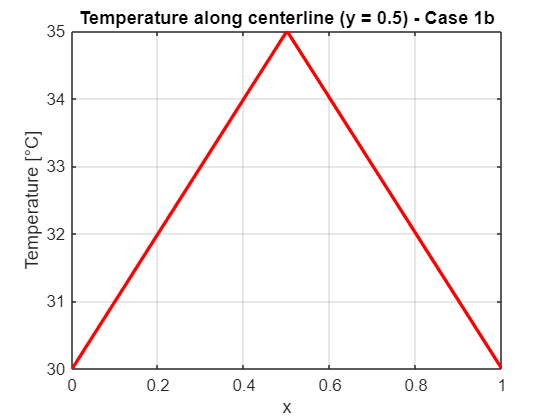


% --- Plot Temperature Along y = 0.5 Line ---
x_vals = linspace(0, 1, 200);
y_vals = 0.5 * ones(size(x_vals));
T_mid = griddata(nodes(:,1), nodes(:,2), T, x_vals, y_vals, 'linear');

figure;
plot(x_vals, T_mid, 'r-', 'LineWidth', 2);
xlabel('x'); ylabel('Temperature [°C]');
title('Temperature along centerline (y = 0.5) - Case 1b');
grid on;